# Getting Started with Neurostim

## Description

Neurostim is a toolbox to run pscyhophysical experiments. It relies on the Psychophysics toolbox for all of its graphics, and sound, while adding scripting, logging, and experimental design features. 

### Prerequisites

Neurostim requires 

- Matlab R2016 or later

- Psychophysics Toolbox 3 

- Some plugins have additional hard and/or software dependencies, but these are checked at run time.

### Installation 

- Install Psychtoolbox. The Psychtoolbox-3 library must be installed prior to the use of Neurostim. For comprehensive instructions on how to install Psychtoolbox, please visit  [http://psychtoolbox.org/download](http://psychtoolbox.org/download)

- Clone Neurostim. Cloning the repository (https://github.com/klabhub/neurostim) to your machine has the advantage that you can update easily, and that you can contribute bug fixes. It does, however, require familiarity with git. Alternatively, you can download the latest version in ZIP format.

-  Add the folder in which you cloned/unpacked neurostim to MATLAB's search path. Only the top folder needs to be added to the path. 

- Make a copy of neurostim/myRig.m, and adapt it to your  needs.

## Features

The Neurostim toolbox has the following features:

- A set of built-in visual stimuli (Gabor, Grating, Random Dot Kinematograms, Noise,...

- A set of built-in plugins to communicate with external devices (Eyelink, Blackrock, Ripple, Measurement Computing, Open EPhys, EGI, Starstim, Datapixx)

- Adaptive parameter estimation methods (Quest, Psy, Staircase)

- Color calibration (I1pro) and calibrated color stimulus presentation (ViewPixx)

- Pre-specified behavioral control objects (fixation, saccades, key presses)

- Remote monitoring of an experiment 

- Built-in experimental design specification (e.g. factorial variation of parameters, with randomization at trial, block, and experiment elvel)

- Precise and complete logging of all variables set/used in the experiment. 

- Functionality can be extended easily with user-defined stimulus classes and plugins.

- A GUI to run experiments in production mode (see nsGuiTutorial.mlx)

### Examples/Demos

The demos are the best place to start. Each demo is documented extensively and shows how to setup an  experiment, add stimuli, add behavioral control, and include plugins to interact with external devices. 

Here is a suggested path through the demos:

-  Basic setup 

behaviorDemo

- Eye movement control

behaviorDemo %  (fixation)
fixateThenChooseDemo; %  (Fixate, then give an "answer" by looking at one of two dots)

- Adaptive parameter estimation

adaptiveDemo %(Quest, Staircase, Psi)

-  Retrieving and Analyzing Neurostim Output

taeDemo

- Calibrated luminance and color

lumDemo
xyLDemo
xylTextureDemo

- Complex visual stimuli

fastFilteredImageDemo
noiseGridDemo

- Interaction with external devices 

rippleDemo  % Ripple Neurophysiology Hardware (Trellis)
starstimDemo  % Neuroelectrics  StarStim tDCS/tACS/tRNS device
egiDemo        % EGI EEG recording hardware
stgDemo        % MultiChannel Systems STG stimulation hardware
daqDemo         % Data acquisition with AD converter

- High resolution graphics

lumM16Demo % (VPIXX monochrome )
responsePixxDemo % (VPIXX using the response box )

## Extending Neurostim

At some point, the built-in stimuli (neurostim.stimuli) and plugins (neurostim.plugins) may not do exactly what you need in your experiment. That is when you will write your own class definition to define a new stimulus or (hardware) plugin:

Neurostim's class hierarchy looks like this : 

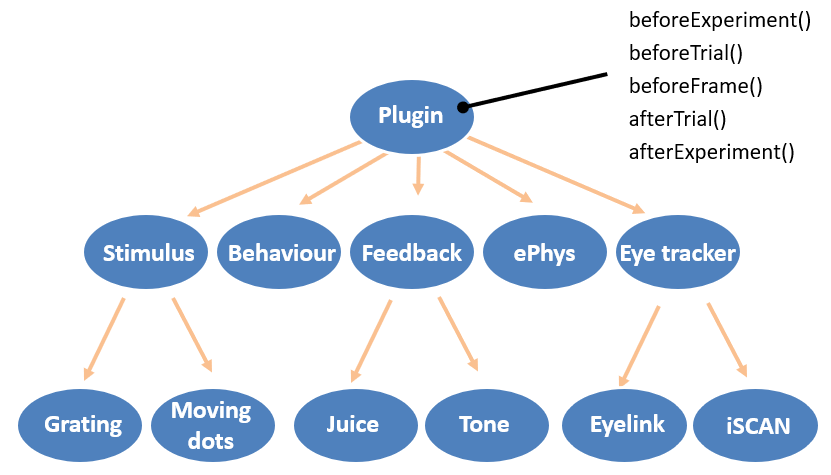

 The superclass ‘plugin’ is the class from which all other classes are derived. It contains properties and functions that are required by all derived sub-classes. 

The main design principle is that a plugin has functions (with self-explanatory names) that execute at certain times in the experiment. 

- `beforeExperiment`

- `beforeBlock`

- `beforeTrial`

- `beforeFrame`

- `afterFrame`

- `afterTrial`

- `afterBock`

- `afterExperiment`

Note that most plugins only do somehting in a subset of these, and you may be surprised at how little code is needed to develop your own stimulus. The best way to see what is needed, is to inspect one of the built-in classes that does something similar.

For instance, if you want to develop a new visual stimulus, have a look at `neurostim.stimuli.rdp `for the random dots stimulus class; it implements only what is needed to show the dots, and to move them to a new position before each frame. 

If you want to develop a new hardware plugin, then have a look at one of the plugins commuinicating with electrophysiology hardware (`blackrock, ripple, egi`).

Behavioral control is a little more complex as it is implemented using finite state machines. To add a behavior, study behaviors.fixate, then add your own states and transition rules.

Notet that in all cases, becuase Neurostim uses an object-oriented class hierarchy, you can easily reuse code by class derivation (See [Hierarchies of Classes - Concepts - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_oop/hierarchies-of-classes-concepts.html)) : you can reuse functionality of the `stimuli.gabor` in your class that shows many Gabors, you can derive from `behaviors.eyeMovement` to create an optokinetic nystagmus class.

### Logging parameters

One of the key features of Neurostim is that all properties are logged and timed, and that you can use of Neurostim functions to "bind" two stimuli to each other at run time (e.g. Gabor is always 10 cm to the right of fixation, but fixation is randomized).

In your plugin, you create such logged parameters with the` plugin.addProperty()` function. For instance,

o.addProperty('numberOfDots', 100);

creates a new dynamic property called numberOfDots and sets its value to 100. After this line, you can use `o.numberOfDots  =10 `to change its value, and both the new value and the time at which it was changed will be loggged internally. 

In the analysis phase you can retreive all values (and times) that     were stored using the `get`() member function of the parameter class. Please see `demos/taeDemo.m `for an example.